clearvars
%here i calc teilor sum function Teilor creates Taylor expansion
syms x h u du ddu dddu ddddu
u_x_add_h = Teilor(x,h,u,du,ddu,dddu,ddddu);
u_x_min_h = Teilor(x,-h,u,du,ddu,dddu,ddddu);


u_x_add_2h = Teilor(x,2*h,u,du,ddu,dddu,ddddu);
u_x_add_3h = Teilor(x,3*h,u,du,ddu,dddu,ddddu);
u_x_min_2h = Teilor(x,-2*h,u,du,ddu,dddu,ddddu);


% result is Taylor expansion
result = 1/h * (1/6 * u_x_min_2h  - 4/3 *u_x_min_h + 11/6 * u - 5/3*u_x_add_h+4/3*u_x_add_2h - 1/3 *u_x_add_3h)

$$result = \frac{\mathrm{du}\,h-\frac{\mathrm{ddddu}\,h^{4}}{4}}{h}$$

%There is num solution
h = pi/10;
N = 20;


A = 1/(6*h) *spdiags([8*ones(N,1),-2*ones(N,1),ones(N,1),-8*ones(N,1), 11*ones(N,1),-10*ones(N,1),8*ones(N,1),-2*ones(N,1),ones(N,1)], ...
    [-N+1,-N+2,-2,-1,0,1,2,3,N-1],N,N);
x = (1:N);
B = -spdiags([sin(x*h)./(3+cos(x*h))]',[0],N,N);

F = ((cos(2*h*x) + 3*cos(x*h))./(3+cos(x*h)))';
U = (A+B)\F;


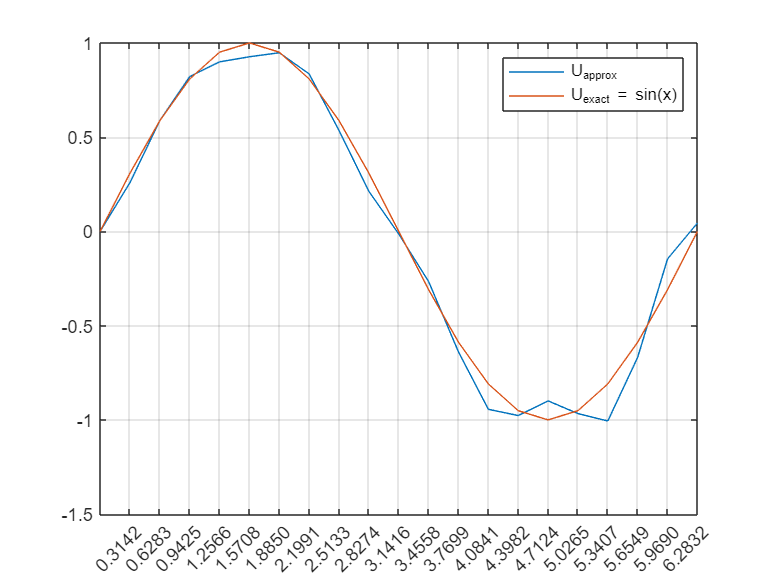

U_real  = sin([0,x*h]);


plot([0,x*h],[0,U']);hold on
plot([0,x*h],U_real);


legend('{U_{approx}}','{U_{exact} = sin(x)}')
xlim([0,2*pi])
xticks(x*h)
grid('on')
hold off

% Calc the error
Ns = 2.^(2:15);
L_inftu = zeros(1,15-2);
L_rms =zeros(1,15-2);
i = 1;

for N = Ns
    h = 2*pi/N;
    A = 1/(6*h) *spdiags([8*ones(N,1),-2*ones(N,1),ones(N,1),-8*ones(N,1), 11*ones(N,1),-10*ones(N,1),8*ones(N,1),-2*ones(N,1),ones(N,1)], ...
        [-N+1,-N+2,-2,-1,0,1,2,3,N-1],N,N);
    x = (1:N);
    B = -spdiags([sin(x*h)./(3+cos(x*h))]',[0],N,N);
    
    F = ((cos(2*h*x) + 3*cos(x*h))./(3+cos(x*h)))';
    U_approx = (A+B)\F;
    U_approx = [0,U_approx'];
    X = [0,x*h];
    U_real  = sin(X);
    err = U_real - U_approx;
    L_infy(i) = max(abs(err));
    L_rms(i) = sqrt(sum(err.^2)/N);
    i= i+1;
end

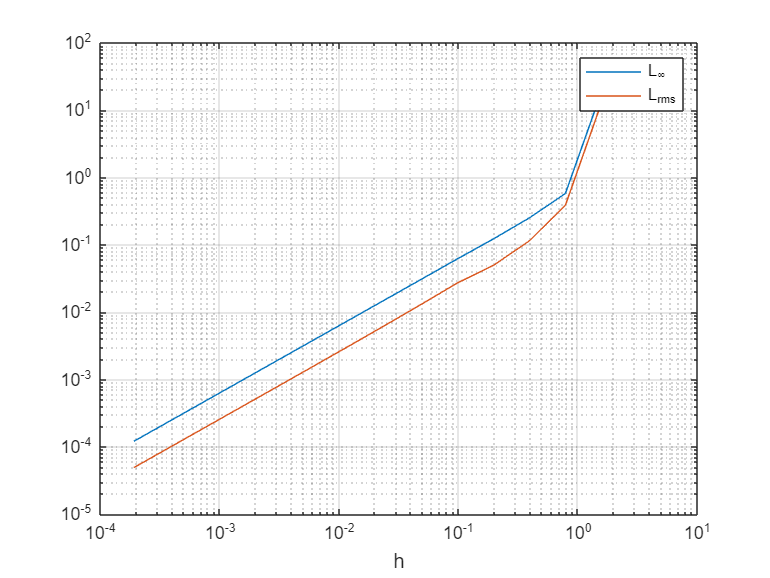

H = 2*pi./Ns;

loglog(H,L_infy); hold on
loglog(H,L_rms)
%loglog(H,H/4)


legend('L_{\infty}','L_{rms}')
xlabel('h')
grid('on')
hold off

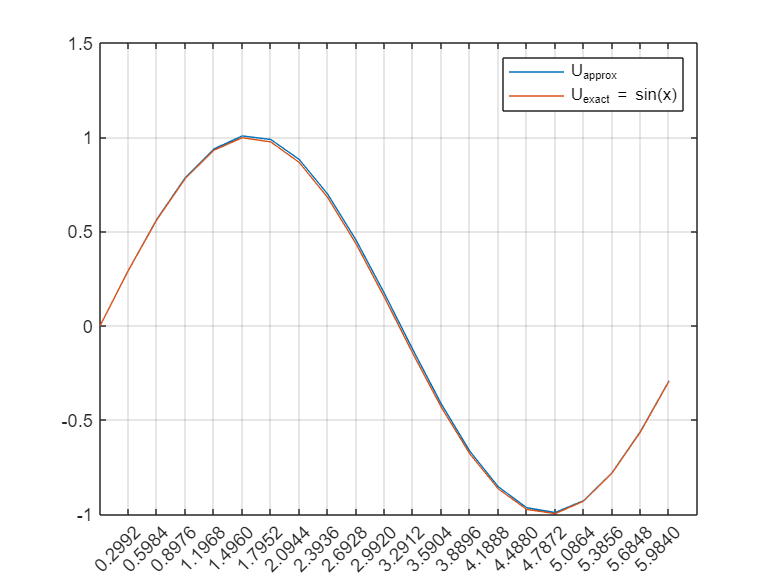

%There is num solution
%h = pi/10;
N = 20;
h = 2*pi/(N+1); % Modified

A = 1/(6*h) *spdiags([8*ones(N,1),-2*ones(N,1),ones(N,1),-8*ones(N,1), 11*ones(N,1),-10*ones(N,1),8*ones(N,1),-2*ones(N,1),ones(N,1)], ...
    [-N+1,-N+2,-2,-1,0,1,2,3,N-1],N,N);
x = (1:N);
B = -spdiags([sin(x*h)./(3+cos(x*h))]',[0],N,N);

F = ((cos(2*h*x) + 3*cos(x*h))./(3+cos(x*h)))';
U = (A+B)\F;

U_real  = sin([0,x*h]);


plot([0,x*h],[0,U']);hold on
plot([0,x*h],U_real);


legend('{U_{approx}}','{U_{exact} = sin(x)}')
xlim([0,2*pi])
xticks(x*h)
grid('on')
hold off

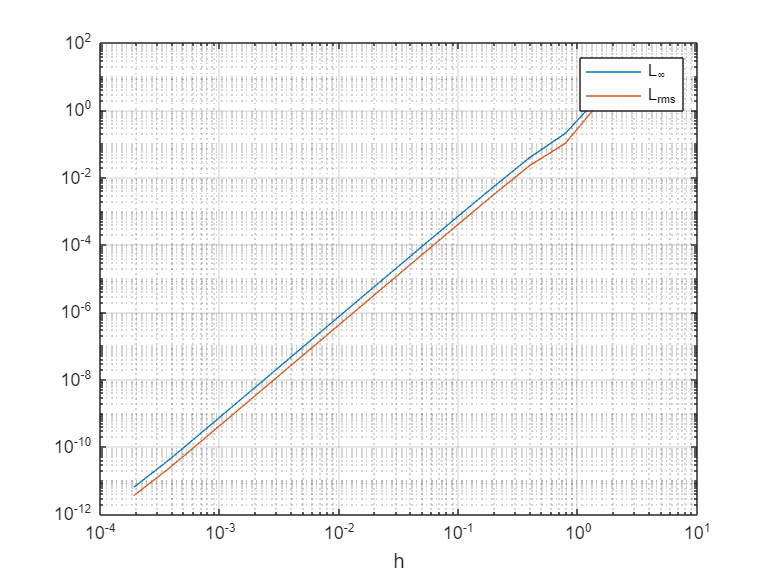

% Calc the error
Ns = 2.^(2:15);
L_inftu = zeros(1,15-2);
L_rms =zeros(1,15-2);
i = 1;

for N = Ns
    %h = 2*pi/N;
    h = 2*pi/(N+1); % Modified
    A = 1/(6*h) *spdiags([8*ones(N,1),-2*ones(N,1),ones(N,1),-8*ones(N,1), 11*ones(N,1),-10*ones(N,1),8*ones(N,1),-2*ones(N,1),ones(N,1)], ...
        [-N+1,-N+2,-2,-1,0,1,2,3,N-1],N,N);
    x = (1:N);
    B = -spdiags([sin(x*h)./(3+cos(x*h))]',[0],N,N);
    
    F = ((cos(2*h*x) + 3*cos(x*h))./(3+cos(x*h)))';
    U_approx = (A+B)\F;
    U_approx = [0,U_approx'];
    X = [0,x*h];
    U_real  = sin(X);
    err = U_real - U_approx;
    L_infy(i) = max(abs(err));
    L_rms(i) = sqrt(sum(err.^2)/N);
    i= i+1;
end
H = 2*pi./Ns;

loglog(H,L_infy); hold on
loglog(H,L_rms)
%loglog(H,H/4)


legend('L_{\infty}','L_{rms}')
xlabel('h')
grid('on')
hold off

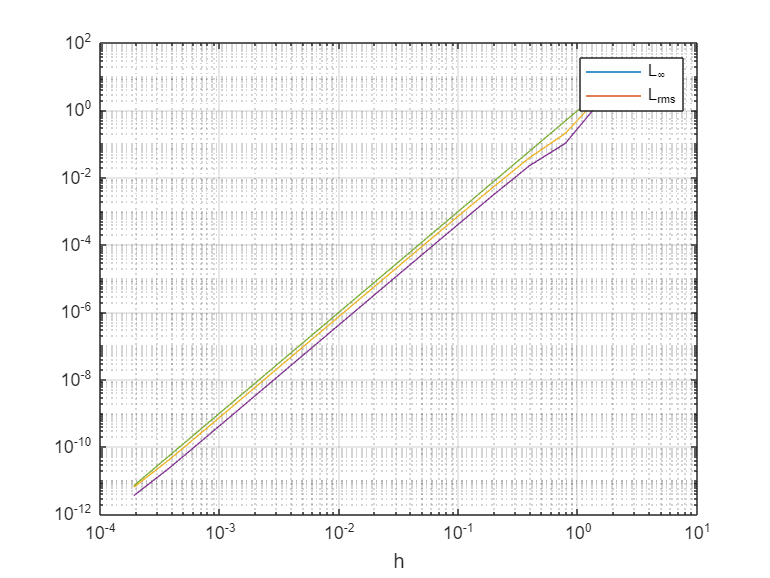


loglog(H,L_infy); hold on
loglog(H,L_rms)
loglog(H,H.^3)


legend('L_{\infty}','L_{rms}')
xlabel('h')
grid('on')
hold off

function res = Teilor(x,h,u,du,ddu,dddu,ddddu)
    res = u + h*du + h^2 /2 *ddu + h^3/6 * dddu + h^4/24 * ddddu;
end
